COM-SGN.110 Introduction to Image and Video Processing

EXERCISE 8, Joonas Palonen 272784

16.11.2020 - 18.11.2020

**1)**

Apply H(u,v) motion blurring with T=1, direction=135 and distance=0.1

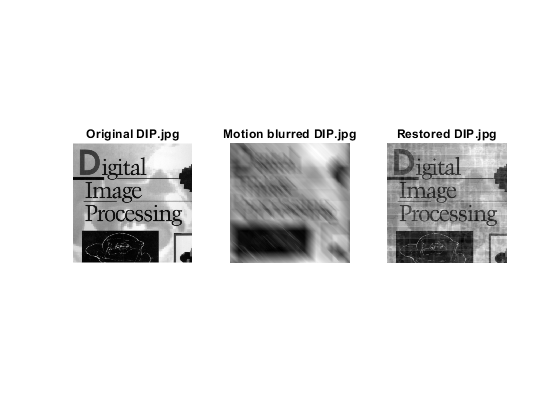

img = double(imread("DIP.jpg"));

[row, col] = size(img);
[u, v] = meshgrid(-row/2:row/2-1, -col/2:col/2-1);

% Calculate the filter
T = 1; a = -0.1; b = -0.1;
s = (u*a+v*b);
h = (T./(pi*(s+0.001))).*sin(pi*s).*exp(-1j*pi*s);

F = fft2(img);              % fourier transform
Fc = fftshift(F);           % move the zero-freq comp. to the center
G = h.*Fc;                  % filter image
gi = ifft2(ifftshift(G));   % inverse shifting and transfrom
img_mb = real(gi);          % real part

% Inverse transform
iF = fftshift(fft2(img_mb));
img_invf = real(ifft2(ifftshift(iF./(h+0.001))));

% Calculate MSE
err1 = immse(img_mb, img);
err2 = immse(img_invf, img);
 
% Plotting
figure(); 
subplot(131); imshow(uint8(img)); title("Original DIP.jpg");
subplot(132); imshow(img_mb, []); title("Motion blurred DIP.jpg");
subplot(133); imshow(img_invf, []); title("Restored DIP.jpg");


% Print MSEs
fprintf('\n The MSE of motion blurred image is %0.2f\n', err1);


 The MSE of motion blurred image is 23386.86


fprintf('\n The MSE of restored image is %0.2f\n', err2);


 The MSE of restored image is 19343.43


**2) **

Restore image with Wiener filter

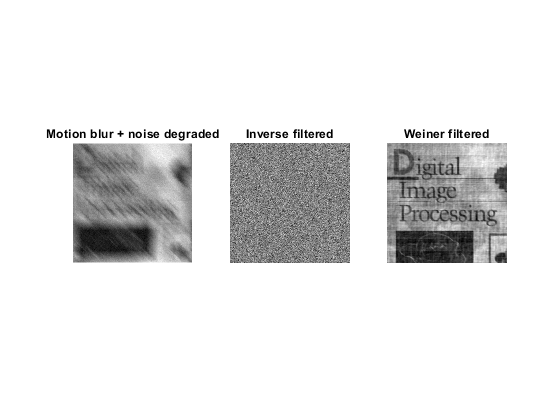

% Add noise with variance 50 and 0 mean
noise = double(sqrt(50)*randn(row,col));
img_mbn = img_mb + noise;

% Apply simple inverse filtering
iF2 = fftshift(fft2(img_mbn));
img_invf2 = real(ifft2(ifftshift(iF2./(h+0.001))));

% Apply the Wiener filter
weiner =  (1./(h+0.001)) .* ( (abs(h).^2) ./ ( (abs(h).^2) + ((abs(fftshift(fft2(noise))).^2) ./ (abs(Fc).^2)) ) ) .* iF2;

% Back to spatial domain
weiner_inv = real(ifft2(ifftshift(weiner)));

% Plotting
figure();
subplot(131); imshow(img_mbn, []); title("Motion blur + noise degraded");
subplot(132); imshow(img_invf2, []); title("Inverse filtered");
subplot(133); imshow(weiner_inv, []); title("Weiner filtered");

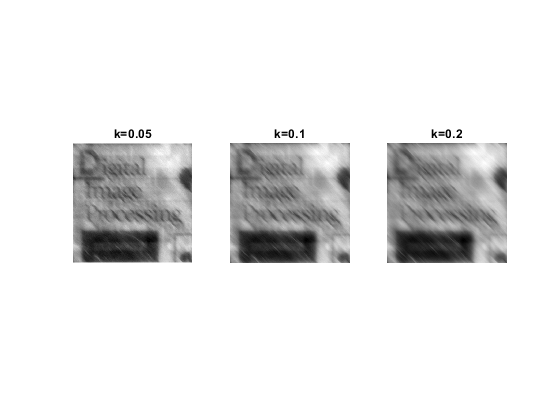


% Testing with unknown signal to noise ratios
weiner1 =  (1./(h+0.001)) .* ( (abs(h)).^2 ./ ((abs(h)).^2 + 0.05)) .* iF2;
weiner2 =  (1./(h+0.001)) .* ( (abs(h)).^2 ./ ((abs(h)).^2 + 0.1)) .* iF2;
weiner3 =  (1./(h+0.001)) .* ( (abs(h)).^2 ./ ((abs(h)).^2 + 0.2)) .* iF2;

% Back to spatial domain
weiner_inv1 = real(ifft2(ifftshift(weiner1)));
weiner_inv2 = real(ifft2(ifftshift(weiner2)));
weiner_inv3 = real(ifft2(ifftshift(weiner3)));

% Plotting
figure();
subplot(131); imshow(weiner_inv1, []); title("k=0.05");
subplot(132); imshow(weiner_inv2, []); title("k=0.1");
subplot(133); imshow(weiner_inv3, []); title("k=0.2");